# Trabalho 1 - Controle 2

## 1. Ler dados de entrada

filename8ms = '.\Amostragem-8ms.xlsx';
filename3ms = '.\Amostragem-3ms.xlsx';
Tab8ms = readtable(filename8ms)

Tab8ms = 400×2 table
    Tempo    Resposta
    _____    ________

       0         0   
    7968         0   
    7992        37   
    7992        94   
    7988       202   
    8000       285   
    8000       296   
    8000       451   
    7996       512   
    8000       564   
    8000       561   
    7992       581   
    8000       615   
    8000       648   
    8000       552   
    8000       682   


Tab3ms = readtable(filename3ms)

Tab3ms = 600×2 table
    Tempo    Resposta
    _____    ________

       0         0   
    2980         0   
    2996         0   
    2996         3   
    2996        18   
    2988        43   
    2992        74   
    2996       107   
    3004       139   
    3000       147   
    3004       203   
    3004       243   
    3004       241   
    3004       309   
    3004       300   
    3004       367   


## 2. Exibir dados de entrada

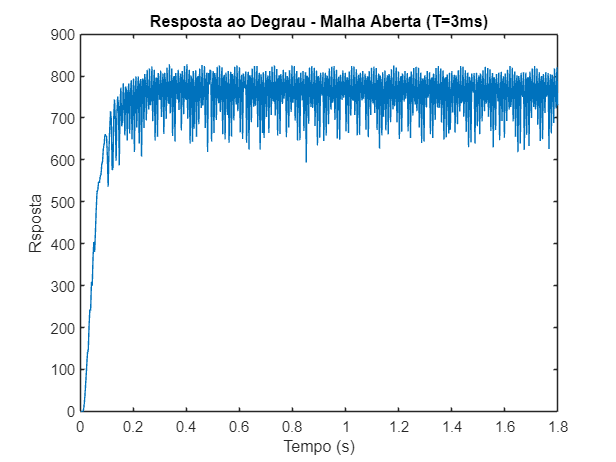

t3ms = 1:length(Tab3ms.Tempo);
t3ms = t3ms * 3*10^-3;

plot(t3ms, Tab3ms.Resposta);
title('Resposta ao Degrau - Malha Aberta (T=3ms)')
xlabel('Tempo (s)')
ylabel('Rsposta')

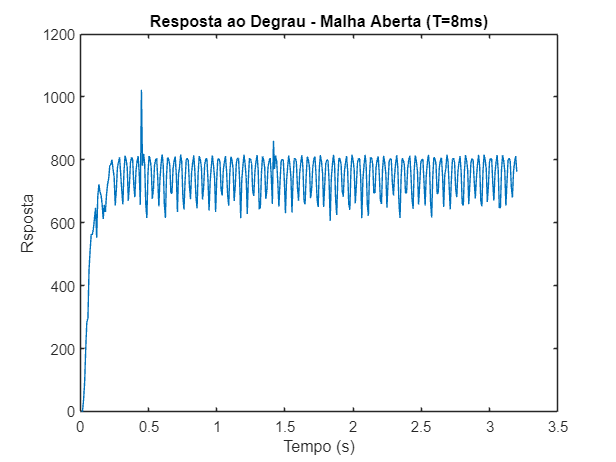

t8ms = 1:length(Tab8ms.Tempo);
t8ms = t8ms * 8*10^-3;

plot(t8ms, Tab8ms.Resposta);
title('Resposta ao Degrau - Malha Aberta (T=8ms)')
xlabel('Tempo (s)')
ylabel('Rsposta')

## 3. FFT da resposta ao degrau

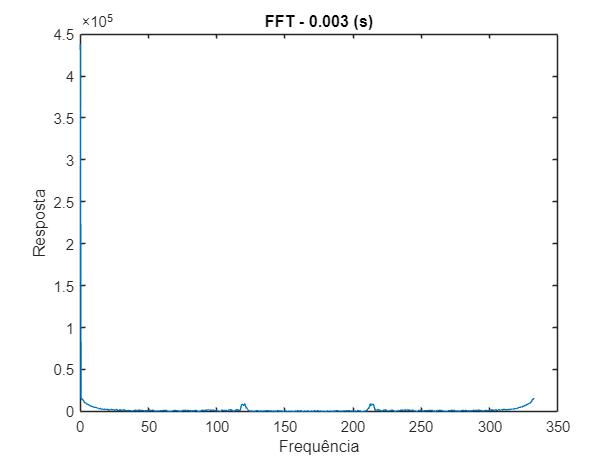

% Chamadas da função
Fs3 = BuildFFT(3* 10^(-3), Tab3ms.Resposta);

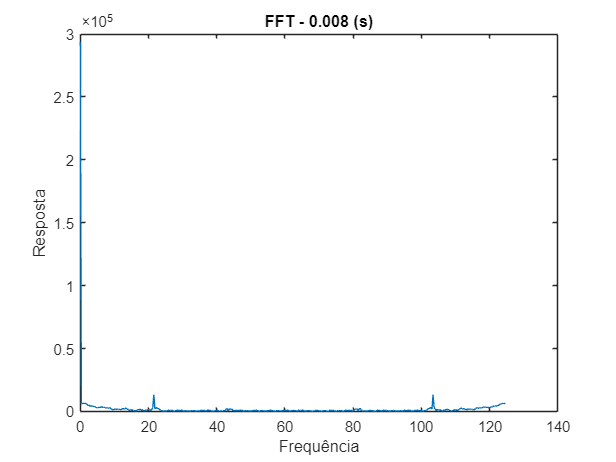

Fs8 = BuildFFT(8 * 10^(-3), Tab8ms.Resposta);

## 4. Projetar o filtro

- Determinar a Frequência Fundamental $\omega = 0; R(\omega) = 294875$

- Determinar Frequência de Corte    $\omega_c(T=3ms) =  0.5$  $  \omega_c(T=8ms) =  0.3$

- Filtrar ruído: Filtro passa baixa de ordem 1

## 5.  Aplicar o filtro e Reconstruir resposta no dominio do tempo

T = 3ms

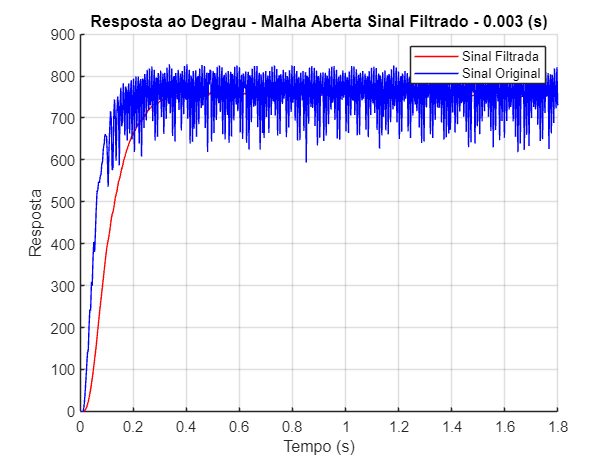

[SinalFiltrado3ms, nun3ms, den3ms] = FilterSignal(1, 3, Tab3ms.Resposta, Fs3, t3ms, 3* 10^(-3));

Ft_fltr3ms = tf(nun3ms, den3ms);
zpk(Ft_fltr3ms)

ans =
 
  0.027504 (s+1)
  --------------
    (s-0.945)
 
Continuous-time zero/pole/gain model.
Model Properties


Ft_fltr3msz = c2d(Ft_fltr3ms, 3*10^-3);
zpk(Ft_fltr3msz)

ans =
 
  0.027504 (z-0.997)
  ------------------
      (z-1.003)
 
Sample time: 0.003 seconds
Discrete-time zero/pole/gain model.
Model Properties


a3ms =  GetStepInfo(Tab3ms.Resposta, SinalFiltrado3ms, t3ms)

Tempo de subida (original): 0.0716 s
Tempo de subida (filtrado): 0.1710 s
Erro relativo tempo de subida: -138.9069

Tempo de acomodação (original): 1.7995 s
Tempo de acomodação (filtrado): 0.3027 s
Erro relativo tempo de acomodação: 83.1782



a3ms = 12.8657

T = 8ms

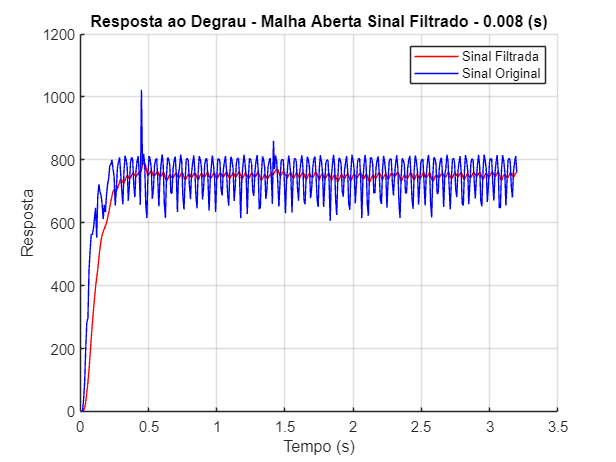

[SinalFiltrado8ms, nun8ms, den8ms] = FilterSignal(1, 3, Tab8ms.Resposta, Fs8, t8ms, 8* 10^(-3));

Ft_fltr8ms = tf(nun8ms, den8ms)

Ft_fltr8ms =
 
  0.07024 s + 0.07024
  -------------------
      s - 0.8595
 
Continuous-time transfer function.
Model Properties


zpk(Ft_fltr8ms)

ans =
 
  0.070236 (s+1)
  --------------
    (s-0.8595)
 
Continuous-time zero/pole/gain model.
Model Properties


Ft_fltr8msz =c2d(Ft_fltr8ms, 8*10^-3)

Ft_fltr8msz =
 
  0.07024 z - 0.06967
  -------------------
       z - 1.007
 
Sample time: 0.008 seconds
Discrete-time transfer function.
Model Properties


a8ms = GetStepInfo(Tab8ms.Resposta, SinalFiltrado8ms, t8ms)

Tempo de subida (original): 0.0993 s
Tempo de subida (filtrado): 0.1801 s
Erro relativo tempo de subida: -81.4823

Tempo de acomodação (original): 3.1976 s
Tempo de acomodação (filtrado): 3.1773 s
Erro relativo tempo de acomodação: 0.6333



a8ms = 12.2130

## 6. Modelar o sistema 

### 6.0 Planta do sistema de primeira ordem


$$G_p(s) = \frac{a}{s+a}$$


### 6.1 Identificar especificações de desempenho

- Constante de tempo


$$a = \frac{1}{\tau}=\frac{1}{66.8*10^(-3)}=14,97 ; C(\tau) = 0,63C_f $$


- Tempo de subida


$$T_r = \frac{2,2}{a}$$


- Tempo de acomodação


$$T_s = \frac{4}{a}$$


### 6.2 Modelo do sistema

a = 14.97;
s = tf('s');
K = 750;
Gp = a * K /(s+a);
Gp_zpk = zpk(Gp)

Gp_zpk =
 
    11228
  ---------
  (s+14.97)
 
Continuous-time zero/pole/gain model.
Model Properties


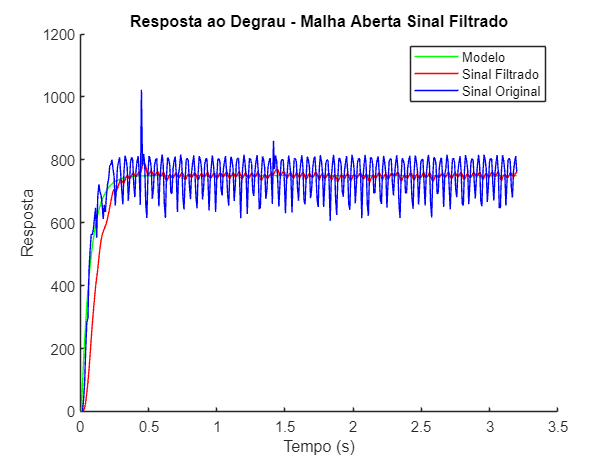

[y, tOut] = step(Gp, t8ms);

figure;
hold on;

plot(t8ms, y, 'color', 'g', 'DisplayName', 'Modelo');
plot(t8ms, SinalFiltrado8ms, 'color', 'r', 'DisplayName', 'Sinal Filtrado');
plot(t8ms, Tab8ms.Resposta, 'color', 'b', 'DisplayName', 'Sinal Original');


title('Resposta ao Degrau - Malha Aberta Sinal Filtrado');
xlabel('Tempo (s)');
ylabel('Resposta');
legend();
hold off;

## 7. Analise das EDs do modelo    

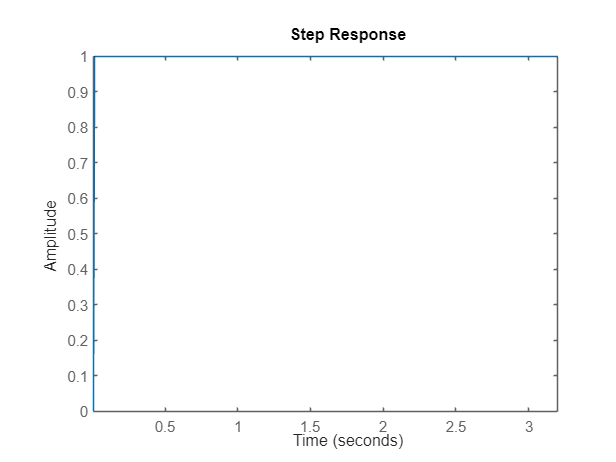

step(feedback(Gp, 1), t8ms)

#### 7.1  especificações de desempenho

info = stepinfo(y, tOut);

% Tempo de acomodação a 2%
Ts = info.SettlingTime;
Tr = info.RiseTime;
Tp= info.PeakTime;
UP= info.Overshoot;
fprintf('Tempo de subida : %.4f s\n', Tr);

Tempo de subida : 0.1468 s


fprintf('Tempo de acomodação: %.4f s\n', Ts);

Tempo de acomodação: 0.2694 s


fprintf('Tempo de pico : %.4f s\n', Tp);

Tempo de pico : 2.3200 s


fprintf('Ultrapassagem percentual : %.4f s\n', UP);

Ultrapassagem percentual : 0.0000 s


#### Objetivo:

-  Atingir %UP = 30%

- Atingir Ts = 0.1s

% Determinando ultrapassagem percentual desejada
up_ideal = 0.3;
Ts_ideal = 0.1;

% Calculando o fator de amortecimento (qsi) e o ângulo correspondente (teta)
qsi = -log(up_ideal) / sqrt(pi^2 + (log(up_ideal))^2);
sigma = 4/Ts_ideal;
w_n = sigma/qsi;
W_d = w_n* sqrt(1-qsi^2);
Sd = -sigma + W_d * 1j

Sd = -4.0000e+01 + 1.0437e+02i

#### 7.2 Projeto do controlador

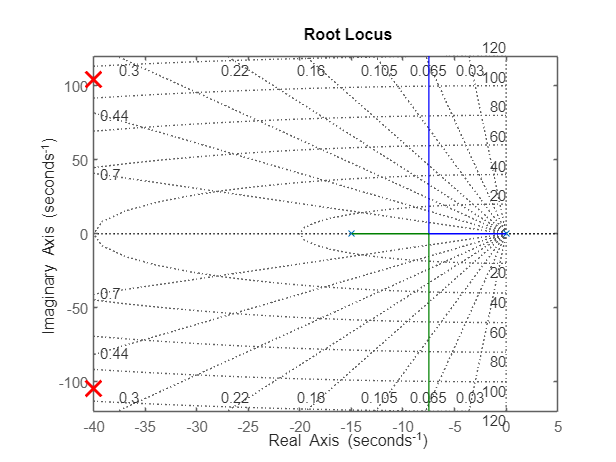

s = tf('s');
Cs = 1/s;

figure;
rlocus(Gp * Cs)

% Plotar o polo desejado no gráfico
hold on;
plot(real(Sd), imag(Sd), 'rx', 'MarkerSize', 15, 'LineWidth', 2);
sgrid();
% Para simetria, marcar também o conjugado
plot(real(Sd), -imag(Sd),'rx', 'MarkerSize',15, 'LineWidth', 2);
hold off;

### 7.2 Condição de fase:

% Condição de Fase
phase = pi - (angle(evalfr(Gp * Cs, Sd)));
fprintf("Fase do controlador %.4f ", phase * 180/pi)

Fase do controlador 34.4541 

teta_c = phase / 2;
z1 = (W_d + (tan(teta_c) * sigma)) / tan(teta_c);
% Condiçao de magnitude
Cs = (s + z1)^2 / s;
K = (abs(1 / evalfr(Gp * Cs, Sd)))

K = 8.6033e-06

phase_pc = angle(evalfr(Gp * Cs, Sd)) * (180/pi);
fprintf('Condicao de fase pos controlador  %.4f', phase_pc);

Condicao de fase pos controlador  180.0000

Cs = K * Cs;
zpk(Cs)

ans =
 
  8.6033e-06 (s+376.6)^2
  ----------------------
            s
 
Continuous-time zero/pole/gain model.
Model Properties


## 7.3 Construir o PID:

Kp = K * (z1 + z1);
Ki = K * (z1 * z1);
Kd = K;

Cs_pid = (Kp + Ki/s + Kd*s)

Cs_pid =
 
  8.603e-06 s^2 + 0.00648 s + 1.22
  --------------------------------
                 s
 
Continuous-time transfer function.
Model Properties


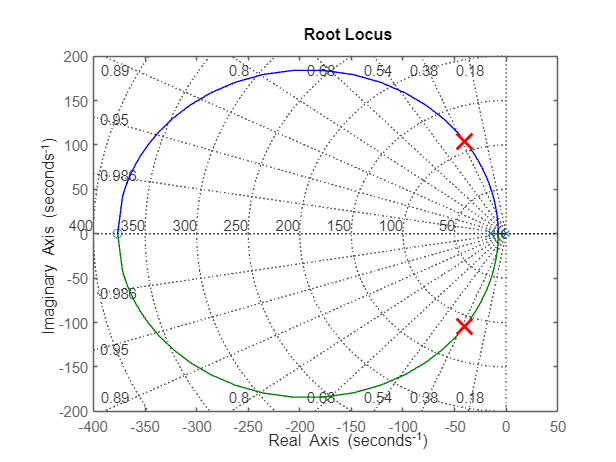

rlocus(Gp * Cs_pid);

% Plotar o polo desejado no gráfico
hold on;
plot(real(Sd), imag(Sd), 'rx', 'MarkerSize', 15, 'LineWidth', 2);
sgrid();
% Para simetria, marcar também o conjugado
plot(real(Sd), -imag(Sd),'rx', 'MarkerSize',15, 'LineWidth', 2);
hold off;

## 8.  Reposta em malha fechada:

T = feedback(Cs_pid * Gp, 1);
% Exibir os polos do sistema em malha fechada
disp('Polos da malha fechada:');

Polos da malha fechada:


disp(pole(T));

   1.0e+02 *

  -0.4000 + 1.0437i
  -0.4000 - 1.0437i



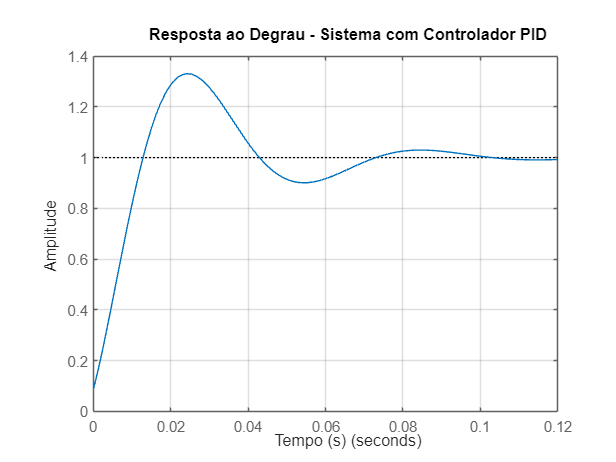

% Validar a resposta ao degrau
figure;
[y_cl, t_cl] = step(T);
step(T);
grid on;
title('Resposta ao Degrau - Sistema com Controlador PID');
ylabel('Amplitude');
xlabel('Tempo (s)');

info = stepinfo(y_cl, t_cl);

% Tempo de acomodação a 2%
Ts = info.SettlingTime;
Tr = info.RiseTime;
Tp= info.PeakTime;
UP= info.Overshoot;
fprintf('Tempo de subida : %.4f ms\n', Tr);

Tempo de subida : 0.0109 ms


fprintf('Tempo de acomodação: %.4f ms\n', Ts);

Tempo de acomodação: 0.0969 ms


fprintf('Tempo de pico : %.4f ms\n', Tp);

Tempo de pico : 0.0242 ms


fprintf('Ultrapassagem percentual : %.4f ms\n', UP);

Ultrapassagem percentual : 34.1678 ms


## 9. Ajuste dos parâmetros do pid

Cs_pid = (Kp*1.065 + (Ki)/s + (Kd*2)*s)

Cs_pid =
 
  1.721e-05 s^2 + 0.006902 s + 1.22
  ---------------------------------
                  s
 
Continuous-time transfer function.
Model Properties


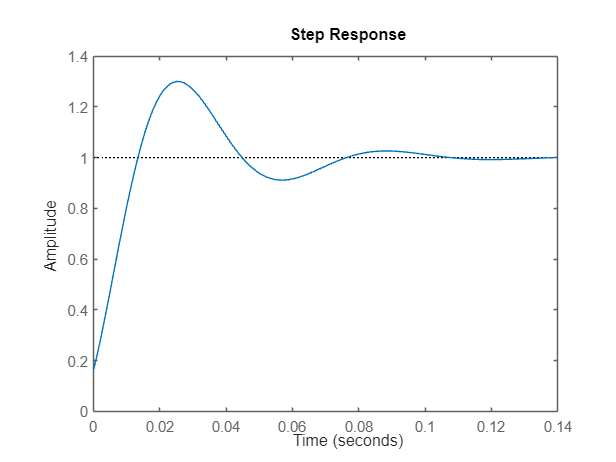

T = feedback(Cs_pid * Gp, 1);
[y_cl, t_cl] = step(T);
step(T);

info = stepinfo(y_cl, t_cl);

% Tempo de acomodação a 2%
Ts = info.SettlingTime;
UP= info.Overshoot;
fprintf('Ultrapassagem percentual : %.4f ', UP);

Ultrapassagem percentual : 30.9613 

fprintf('Tempo de acomodação: %.4f ms\n', Ts);

Tempo de acomodação: 0.1000 ms


#### 9. PID causal

T_zpk = zpk(T)

T_zpk =
 
  0.16191 (s^2 + 401.1s + 7.092e04)
  ---------------------------------
      (s^2 + 77.49s + 1.148e04)
 
Continuous-time zero/pole/gain model.
Model Properties


N = 400;
Cs_causal = (Kp*1.5 + (Ki)/s + (Kd*3.5)*s) * (N/(s + N)) 

Cs_causal =
 
  0.01204 s^2 + 3.888 s + 488.1
  -----------------------------
           s^2 + 400 s
 
Continuous-time transfer function.
Model Properties


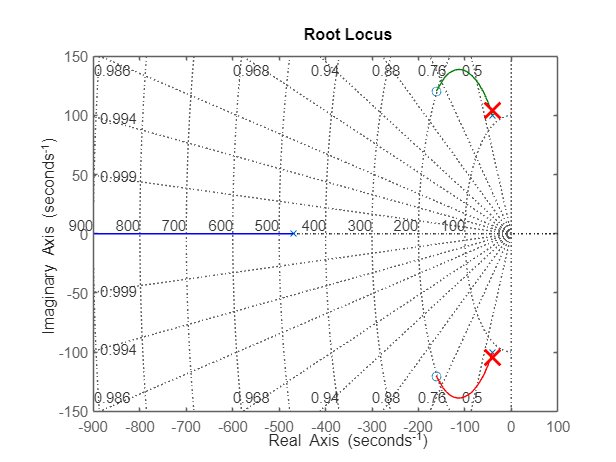

T = feedback(Cs_causal * Gp, 1);
rlocus(T)
% Plotar o polo desejado no gráfico
hold on;

plot(real(Sd), imag(Sd), 'rx', 'MarkerSize', 15, 'LineWidth', 2);
sgrid();
% Para simetria, marcar também o conjugado
plot(real(Sd), -imag(Sd),'rx', 'MarkerSize',15, 'LineWidth', 2);
hold off;

zpk(T)

ans =
 
   135.23 (s^2 + 322.8s + 4.053e04)
  ----------------------------------
  (s+469.3) (s^2 + 80.9s + 1.168e04)
 
Continuous-time zero/pole/gain model.
Model Properties


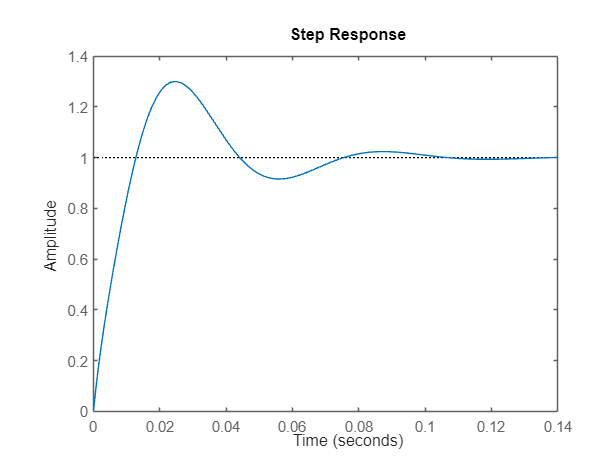

[y_cl, t_cl] = step(T);
step(T);

info = stepinfo(y_cl, t_cl);

% Tempo de acomodação a 2%
Ts = info.SettlingTime;
UP= info.Overshoot;
fprintf('Ultrapassagem percentual : %.4f ', UP);

Ultrapassagem percentual : 30.5961 

fprintf('Tempo de acomodação: %.4f ms\n', Ts);

Tempo de acomodação: 0.0966 ms


Cs_causal_z = c2d(Cs_causal, 8 * 10^(-3), 'Tustin') 

Cs_causal_z =
 
  0.01362 z^2 - 0.003258 z + 0.001655
  -----------------------------------
        z^2 - 0.7692 z - 0.2308
 
Sample time: 0.008 seconds
Discrete-time transfer function.
Model Properties


## 10. Aplicando PID na planta

#### 10.1 Discretizando o pid


$$u[n] = K_p \cdot e[n] + K_d \cdot (e[n] - e[n-1]) + K_i \cdot (e[n] + e[n-1])
$$


#### 10.2 Discretizando o filtro